# Gaussian Wave Packet Spreading in Real-Space vs Momentum-Space

Consider a free particle of mass $m$ ($V=0$ everywhere) delocalized in infinite 1D space. The time-independent Schrödinger equation is the same as inside the box, which is


$$\begin{array}{cc}\frac{d^{2} \psi}{d x^{2}}=-k^{2} \psi, \text { where } k \equiv \frac{\sqrt{2 m E}}{\hbar},& \qquad (38)\\ \end{array}$$
 

however, we do not have to impose vanishing boundary conditions on the wave function, so we just take the general solution:


$$\begin{array}{cc}\psi(x)=A e^{i k x}+B e^{-i k x}.& \qquad (39)\\ \end{array}$$


Restoring the time dependence, the wave function becomes combination of right and left moving plane waves:


$$\begin{array}{cc}\Psi(x, t)=\psi(x) \varphi(t)=A e^{i k\left(x-\frac{\hbar k}{2 m} t\right)}+B e^{-i k\left(x+\frac{\hbar k}{2 m} t\right).}& \qquad (40)\\ \end{array}$$
 

Plane waves describe non-physical situation where particles are present with equal probability everywhere in infinite space.

Hence for any values of $A$ and $B$ wave function Eq. (40) is non-normalizable. Let us study $B=0$ solution (plane wave moving to right):


$$\begin{array}{cc}\Psi(x, t)=A e^{i k\left(x-\frac{\hbar k}{2 m} t\right)}& \qquad (41)\\ \end{array}$$
 

and modify it to the **wave packet** (wave function that is concentrated in the finite support)


$$\begin{array}{cc}\Psi(x, t)=\frac{1}{\sqrt{2 \pi}} \int_{-\infty}^{+\infty} \phi(k) e^{i k\left(x-\frac{\hbar k}{2 m} t\right)} d k& \qquad (42)\\ \end{array}$$
 


$$\begin{array}{cc}\phi(k)=\frac{1}{\sqrt{2 \pi}} \int_{-\infty}^{+\infty} \Psi(x, 0) e^{-i k x} d x.& \qquad (43)\\ \end{array}$$
 

The ** Gaussian wave packet** is a free particle with an initial Gaussian-type normalized wave function


$$\begin{array}{cc}\Psi(x, 0)=\left(\frac{1}{\sigma^{2} \pi}\right)^{1 / 4} e^{-\frac{x^{2}}{2 \sigma^{2}}+i k_{0} x}.& \qquad (44)\\ \end{array}$$
 

Next, using symbolic calculation below we determine the Fourier transform of the initial wave function:


$$\begin{array}{cc}\phi(k)=\left(\frac{\sigma^{2}}{\pi}\right)^{1 / 4} e^{-\frac{\sigma^{2}\left(k-k_{0}\right)^{2}}{2}}& \qquad (45)\\ \end{array}$$
 

syms x y k t sigma h m k0 
assume(x,'real')
assume(k,'real')
assume(t>0)
assume(sigma>0)
assume(h>0)
assume(m>0)
assume(k0,'real')

phi = simplify(fourier( (1/(pi*sigma^2))^(1/4)*exp(-x^2/(2*sigma^2)+1i*k0*x), x,k))

$$phi = \frac{\sqrt{\sigma }\,{\mathrm{e}}^{-\frac{\sigma^{2}\,{\left(k-k_{0}\right)}^{2}}{2}}}{\pi^{1/4}}$$

And the wave function at any time is


$$\begin{array}{cc}\Psi(x, t)=\frac{1}{\left(\sigma^{2} \pi\right)^{1 / 4} \gamma} \exp \left(-\frac{k_{0} \sigma^{2}}{2}+\frac{\left(k_{0} \sigma^{2}+x i\right)^{2}}{2 \sigma^{2} \gamma^{2}}\right), \quad \text { where } \gamma=\sqrt{1+i \hbar t /\left(m \sigma^{2}\right)}.& \qquad (46)\\ \end{array}$$
 

psi = simplify( ifourier((sigma^2/pi)^(1/4) * exp(-sigma^2*(k-k0)^2/2-1i*k^2*t*h/(2*m)) ,k,x))

$$psi = \frac{\sqrt{m}\,\sqrt{\sigma }\,{\mathrm{e}}^{\frac{-h\,t\,{k_{0}}^{2}\,\sigma^{2}+2\,m\,k_{0}\,\sigma^{2}\,x+\mathrm{i}\,m\,x^{2}}{2\,\left(h\,t-m\,\sigma^{2}\,\mathrm{i}\right)}}}{\pi^{1/4}\,\sqrt{m\,\sigma^{2}+h\,t\,\mathrm{i}}}$$

To explore the spreading of Gaussian wave packet, we plot the probability distribution, which is


$$\begin{array}{cc}|\Psi(x, t)|^{2}=\frac{1}{\sigma \mu \sqrt{\pi}} e^{-\frac{\left(x-\frac{\hbar k_{0}}{m} t\right)^{2}}{\sigma^{2} \mu^{2}}}, \quad \text { where } \mu=\sqrt{1+\frac{\hbar^{2} t^{2}}{m^{2} \sigma^{4}}} .& \qquad (47)\\ \end{array}$$
 

rho = simplify(abs(psi).^2)

$$rho = \frac{m\,\sigma \,{\mathrm{e}}^{-\frac{\sigma^{2}\,{\left(m\,x-h\,k_{0}\,t\right)}^{2}}{h^{2}\,t^{2}+m^{2}\,\sigma^{4}}}}{\sqrt{\pi }\,\left|m\,\sigma^{2}+h\,t\,\mathrm{i}\right|}$$

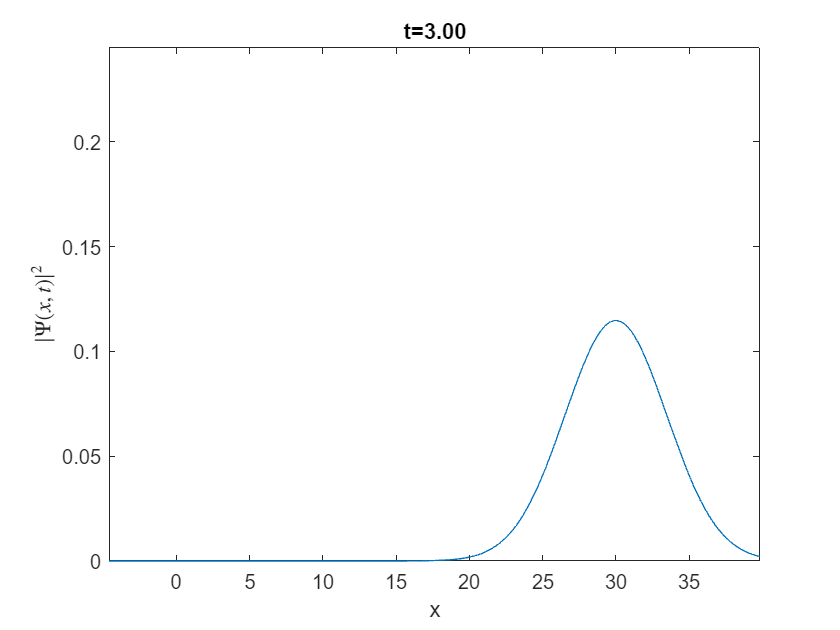

% 1-D plot
mass = 0.3;
sigma0 = 2.3;
speed = 3;
rho1d = subs(rho,[m,h,sigma,k0],[mass,1,sigma0,speed]);
figure;
% Create the animation
tmin = 0; tmax = 3;
sigmat = sigma0 * sqrt(1+tmax^2/mass^2/sigma0^4);
centert = speed*tmax/mass;
for t_ = tmin:.1:tmax
    fplot(subs(rho1d,t,t_))
    xlabel('x');
    ylabel('$|\Psi(x,t)|^2$',Interpreter='latex');
    title(sprintf('t=%.2f', t_));
    ylim([0,1/sigma0/sqrt(pi)]);
    if speed > 0
        xlim([-sigma0*2 sigmat*2+centert]);
    else
        xlim([-sigmat*2+centert sigma0*2]);
    end
    drawnow
end


% 2-D plot
mass = 1;
sigma0 = 3.7;
speed = 0.5;
rho2d = subs(rho,(m*x-h*k0*t)^2,((m*x-h*k0*t)^2+(m*y-h*k0*t)^2))

$$rho2d = \frac{m\,\sigma \,{\mathrm{e}}^{-\frac{\sigma^{2}\,\left({\left(m\,x-h\,k_{0}\,t\right)}^{2}+{\left(m\,y-h\,k_{0}\,t\right)}^{2}\right)}{h^{2}\,t^{2}+m^{2}\,\sigma^{4}}}}{\sqrt{\pi }\,\left|m\,\sigma^{2}+h\,t\,\mathrm{i}\right|}$$

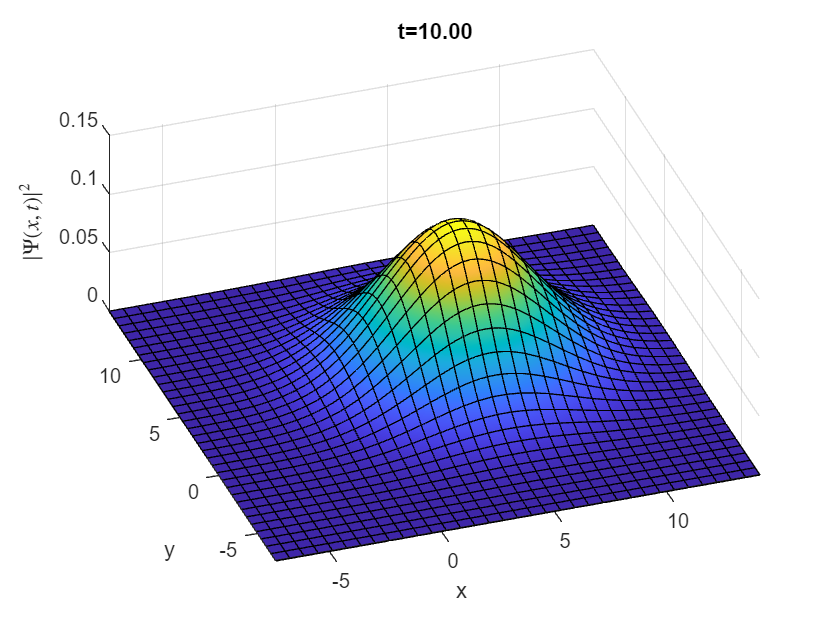

rho2d = subs(rho2d,[m,h,sigma,k0],[mass,1,sigma0,speed]);
peak = 1/sigma0/sqrt(pi);
% Create the animation
figure;
tmin = 0; tmax = 10;

sigmat = sigma0 * sqrt(1+tmax^2/mass^2/sigma0^4);
centert = speed*tmax/mass;

for t_ = tmin:.4:tmax
    fsurf(subs(rho2d,t,t_))
    xlabel('x');
    ylabel('y');
    zlabel('$|\Psi(x,t)|^2$',Interpreter='latex');
    title(sprintf('t=%.2f', t_));
    if speed > 0
        xlim([-sigma0*2 sigmat*2+centert]);
        ylim([-sigma0*2 sigmat*2+centert]);
    else
        xlim([-sigmat*2+centert sigma0*2]);
        ylim([-sigma0*2 sigmat*2+centert]);
    end
    zlim([0 peak]);
    view([-19,56])
    drawnow
end 

## FFT and normalization

Other than analytical solution, we could also use Fast Fourier Transform (FFT) to perform numerical analysis, which is important especially when there is no explicit analytical expression available for the Fourier transform of a wave function. We will use the Gaussian wave packet as an example, to compare results obtained using FFT with the analytical approach used above. Say we have a periodic 1D Gaussian wave packet $\Psi(x, 0)=\pi^{-1 / 4} e^{-x^{2} / 2+i x}$, sampled symmetrically at a $N$ uniform mesh with mesh size $h$ . All parameters in the snippet below are set to 1 for simplicity.

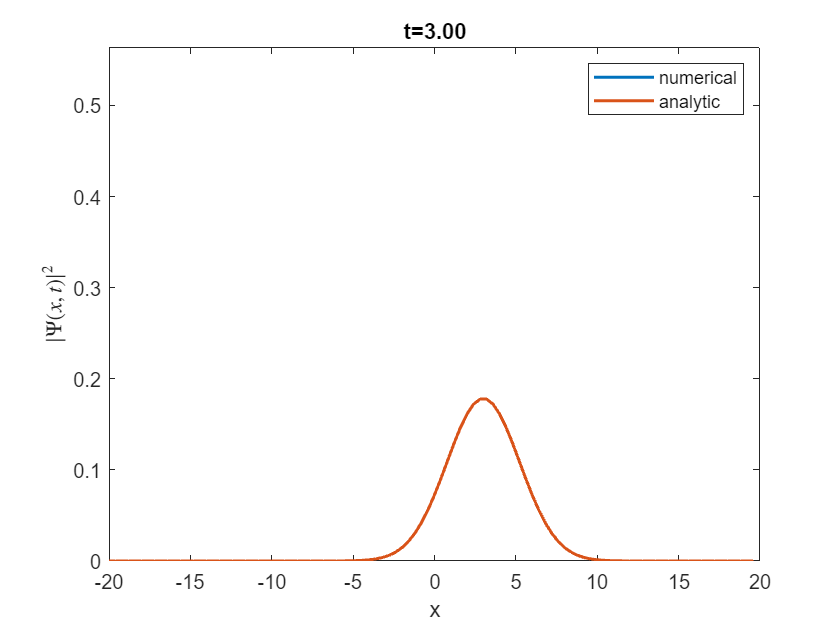

psi = @(x) exp(-x.^2/2+1i*x)/pi^(1/4);
Psi = @(x,t) 1/sqrt(1+1i*t)/pi^(1/4)*exp(-0.5+(1+1i*x).^2./2/(1+1i*t));
N =100;
h =0.4;

L = N*h;
x = ((0:N-1)-floor(N/2))*h;
psi0 = psi(x);
rho0 = abs(psi0).^2;
phi0 = fft(psi0);
k = [0:floor(N/2), floor(-N/2)+1:-1]*2*pi/L;

figure
% Create the animation
tmin = 0; tmax = 3;
for t_ = tmin:.1:tmax
    phi0e = phi0 .* exp(-1i*t_/2*k.^2);
    Psit = ifft(phi0e);
    rhot = abs(Psit).^2;
    Psit_a = Psi(x,t_);
    rhot_a = abs(Psit_a).^2;
    
    plot(x,rhot,x,rhot_a);
    ylim([0,max(rho0)]);
    xlabel('x');
    ylabel('$|\Psi(x,t)|^2$',Interpreter='latex');
    title(sprintf('t=%.2f', t_));
    legend("numerical","analytic");
    drawnow
end

By using FFT, the normalization of wave functions remained perfect as we shall see below.

sum(rho0)*h

ans = 1.0000

sum(rhot)*h

ans = 1.0000

When using FFT, we assume implicitly that the wave function is periodic in terms of $L$, which is the length of the sampled interval. By using large enough $L$, such that there are enough buffer regions on both sides where the magnitude of the wave function is sufficiently small, the influence due to the periodicity assumption could be almost eliminated. Besides, the mesh size has a significant effect on the smoothness of the curve. The finer mesh we choose, the smoother curve we will get.

## References

1.[Teaching Quantum Mechanics with MATLAB](https://serc.carleton.edu/matlab_computation2016/essays/160271.html)

2. [Double-Slit Experiment in MATLAB](https://www.mathworks.com/matlabcentral/fileexchange/122897-double-slit-and-scattering-two-quantum-particles?s_tid=srchtitle)  